# Summary of PET raw data

Reads test h5 file from PETSIRD and plots sample of energies, detector positions and LORs

Copyright (C) 2023 University College London 

SPDX-License-Identifier: Apache-2.0

Author: David Atkinson

FIle developed quickly from a "reverse engineering" of supplied example test.h5 file.


ffn = fullfile('data','test.h5') ;

if ~isfile(ffn)
    warning("Not found on path: "+ffn)
end

% Output minimal h5 information
disp(" ")

h5disp(ffn,'/','min')

HDF5 test.h5 
Group '/' 
    Group '/PrdExperiment' 
        Dataset '$yardl_schema' 
        Dataset 'header' 
        Dataset 'timeBlocks' 



dh  = h5read(ffn,'/PrdExperiment/header') ;
dtB = h5read(ffn,'/PrdExperiment/timeBlocks') ;

if dh.scanner.modelName.has_value ~= 0
    disp("Scanner Model name: "+dh.scanner.modelName.value)
else
    disp("Scanner Model Name not available")
end

Scanner Model Name not available



disp("Subject id: " + dh.exam.value.subject.id{1} )

Subject id: 123456




% detectors is a struct with fields id,x,y,z. Each field is [ndetector 1]
detectors = dh.scanner.detectors{1} ;     % 
tofBinEdges = dh.scanner.tofBinEdges{1} ; % [ntofBinEdges 1]
tofResolution = dh.scanner.tofResolution ;
energyBinEdges = dh.scanner.energyBinEdges{1} ; % 
energyResolutionAt511 = dh.scanner.energyResolutionAt511 ;
listmodeTimeBlockDuration = dh.scanner.listmodeTimeBlockDuration ;

disp("TOF resolution: "+tofResolution+", num TOF bins: "+(length(tofBinEdges)-1) + ...
    " Energy Resn at 511: "+energyResolutionAt511+" listmodeTimeBlockDuration: "+ ...
    listmodeTimeBlockDuration)

TOF resolution: 9.4, num TOF bins: 300 Energy Resn at 511: 0.11 listmodeTimeBlockDuration: 1


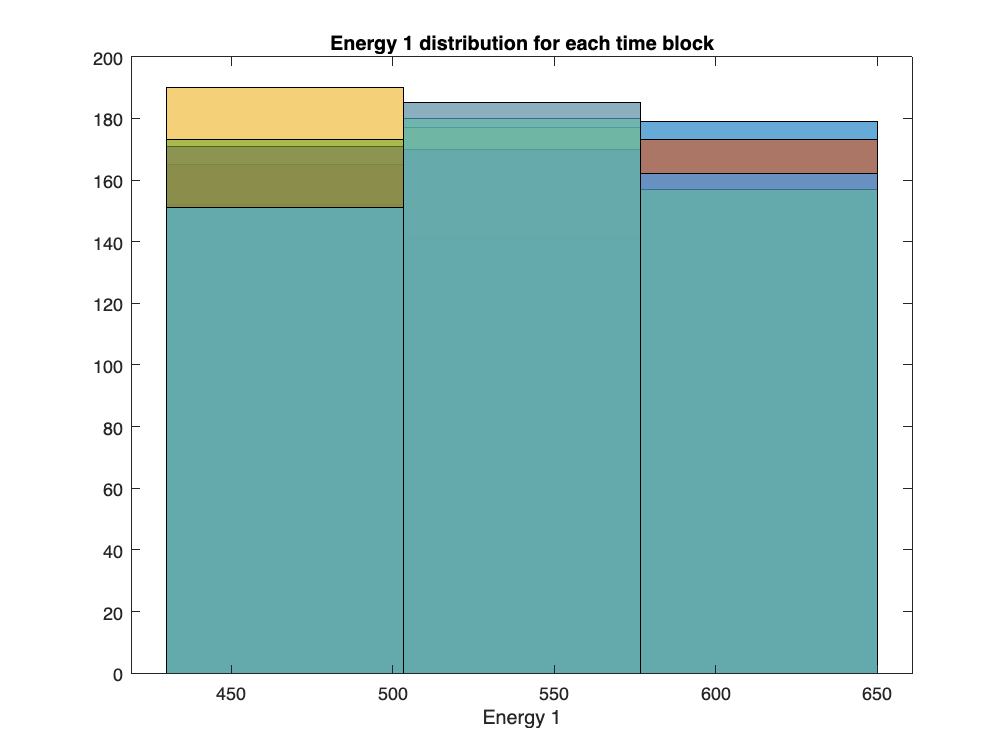


% Time Block data
% promptEvents
pE  = dtB.promptEvents ; % pE {ntimeblocks}  fields: detector1Id, detector2Id, tofIdx, energy1Idx, energy2Idx
ntB = length(pE) ;

energyBinWidths = diff(energyBinEdges) ;
energyBins = energyBinEdges(1:end-1) + energyBinWidths/2 ;

% -- Histogram of energies for Detector 1 at each time block
figure(Name="Energy 1 indices")
for itB = 1: ntB
    energy1Idx_thisBlock = pE{itB}.energy1Idx ;
    hist = histogram(energyBins(1+energy1Idx_thisBlock)) ; % 0-based energy1Idx
    hist.BinEdges = energyBinEdges(:)' ; % make a row vector
    hold on
end
xlabel("Energy 1")
title("Energy 1 distribution for each time block")


% Plot Detector Locations in x and y
dz = unique([detectors.z]) ; % Check only one z value
if length(dz) > 1
    warning("More than 1 detector z location")
end

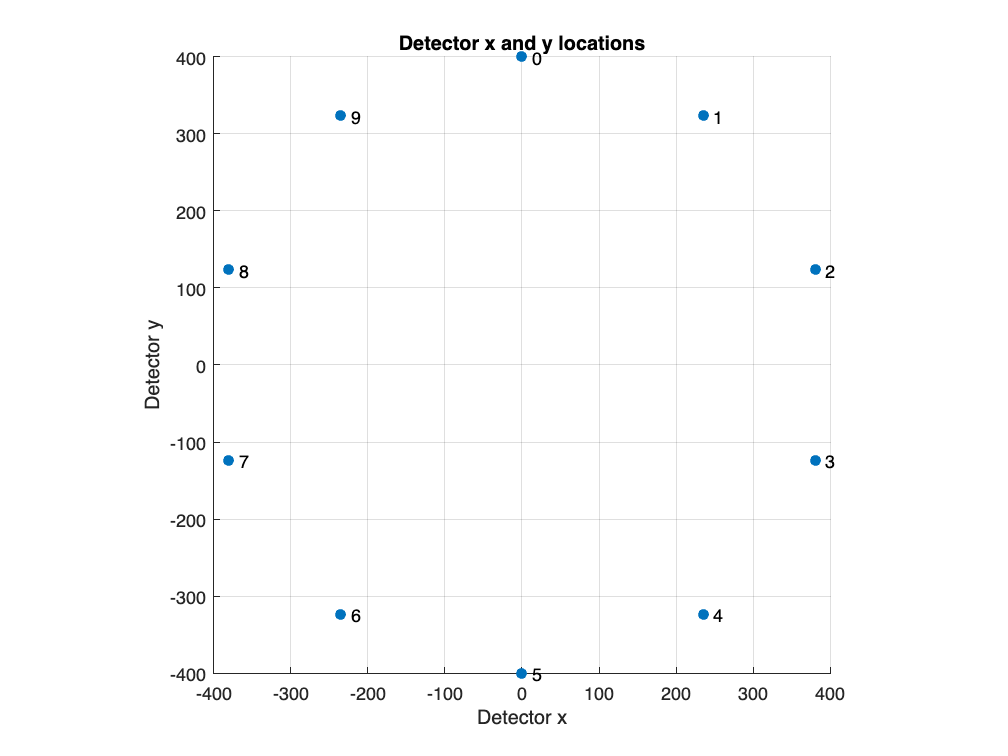


figure(Name="Detector Locations")
nDetectors = size(detectors.id,1) ;
scatter(detectors.x, detectors.y, "filled")
hold on
txtlabel = cell({});
for idet = 1:nDetectors
    txtlabel{idet} = ['  ',num2str(detectors.id(idet))] ; % text labels
end
text(detectors.x, detectors.y, txtlabel, "FontSize",10 )
axDet=gca;
axis square, grid on
xlabel('Detector x'), ylabel('Detector y')
title("Detector x and y locations")

XData = axDet.XLim ;
YData = axDet.YLim ;


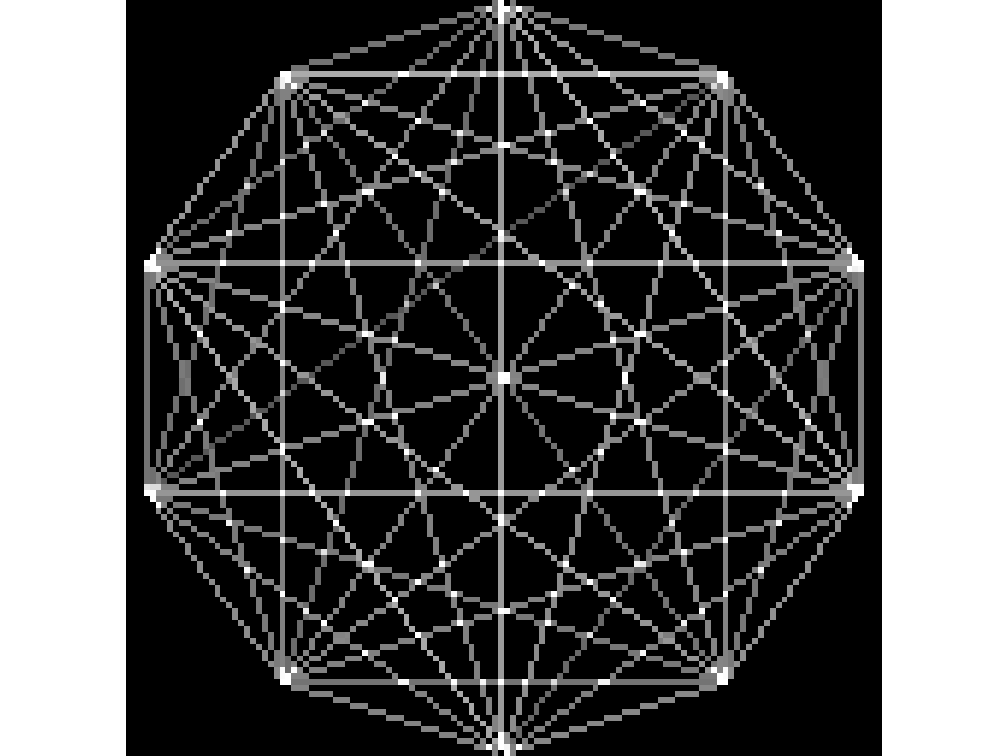



%  Simple back projection by summing lines of response.
%  Could improve by converting roi from line to roipoly using detector
%  geometry for polygon vertices.
figure(Name="Back Proj")
nBP = 128 ;
img = zeros([nBP nBP]) ; % image of zeros in which to accumulate LOR
axBP = gca ;
imshow(img,[],'XData',XData,'YData',YData,'Parent',axBP) ;
hold on

for itB = 1: ntB
    npE_thisBlock = size(pE{itB}.detector1Id,1) ; 
    for ipE_thisBlock = 1: npE_thisBlock
        % set up line roi, convert to mask, sum
        det1x = detectors.x(pE{itB}.detector1Id(ipE_thisBlock)+1) ;
        det2x = detectors.x(pE{itB}.detector2Id(ipE_thisBlock)+1) ;
        det1y = detectors.y(pE{itB}.detector1Id(ipE_thisBlock)+1) ;
        det2y = detectors.y(pE{itB}.detector2Id(ipE_thisBlock)+1) ;

        roi = images.roi.Line(axBP,'Position',[det1x det1y ; det2x  det2y]) ;
        bw = createMask(roi) ; % mask at img resolution
        img = img + bw ; % accumulate LORs
        delete(roi)
    end
end
imshow(img,[0 prctile(img(:),99)],'XData',XData,'YData',YData,'Parent',axBP) ;
title('Accumulated LOR')